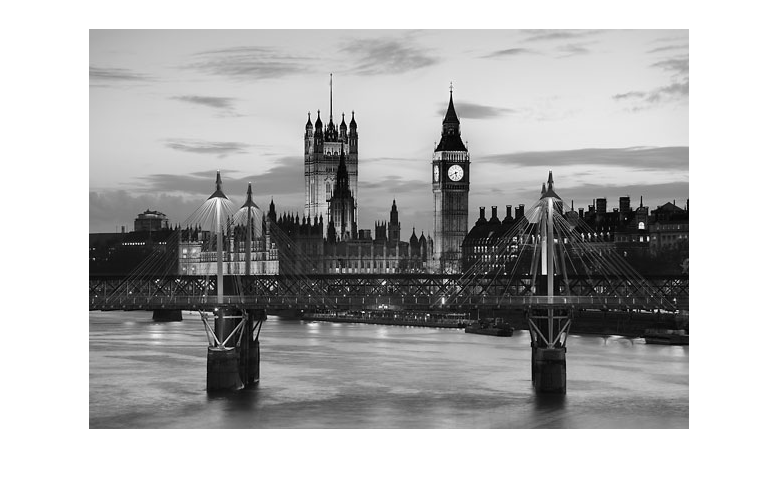

im1 = imread("bigben.jpg");
im1 = rgb2gray(im1);
imshow(im1)

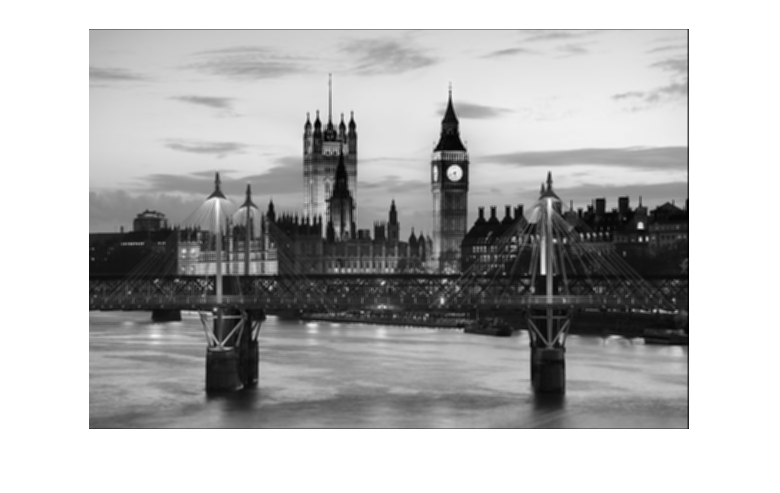

count = 1;

im1 = padarray(im1, [1 1]);

[m, n] = size(im1);
for i = 1:m
    for j = 1:n
        IM1(count) = im1(i, j);
        count = count + 1;
    end
end
IM1 = double([IM1 zeros(1, 10)]);
IM3 = double(zeros(400, 600));
b = [602, -602, 1, -1, -601, -603, 601, 603, 0];
pos = 605;
for i = 1:400
    for j = 1:600
        IM3(i, j) = (IM1(pos+b(9)) + IM1(pos+b(1)) + IM1(pos+b(2)) + IM1(pos+b(3)) + IM1(pos+b(4)) + IM1(pos+b(5)) + IM1(pos+b(6)) + IM1(pos+b(7)) + IM1(pos+b(8)))/9;
        pos = pos +1;
        count = count + 1;
    end
    pos = pos + 2;
end
 
imshow(IM3, [])

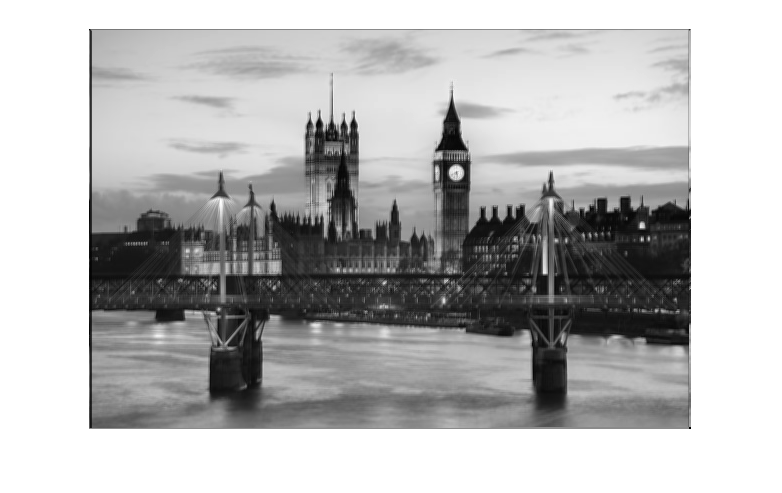


% Write the table to a CSV file
writematrix(IM1,'image.csv')

t = readmatrix("smite.txt");
count = 1;
for i = 1:400
    for j = 1:600
        im2(i, j) = t(count, 1);
        count = count + 1;
    end
end

imshow(im2, [])